# This is matlab script to build FFT spectrum for EField and BField

%%%It include IDL function to restore and read the file
%%%%%%This script is to read and plot KAW spectrum and time series and compare E/B with prediction of KAW dispersion

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Here we read in sav files to read KAW E1,E2,B1,B2 of MMS data (E and B data are not completely shown here and can be obtained using SPEDAS software)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
data=restore_idl('20200929_0620_0700_paper.sav');

C:\Program Files\matlab_cdf381_patch\saniya_code\saniya_code\20200929_0620_0700_paper.sav
creating BX:  double  ARRAY: 38400      1
creating BX_TIME:  double  ARRAY: 38400      1
creating EY:  double  ARRAY: 76799      1
creating V_PART:  double  ARRAY: 111    1
creating V_PART_TIME:  double  ARRAY: 111    1
creating V_EXB:  double  ARRAY: 38400      1


Eperp=(data.EY)';    % Ey here is actually E2 data in the field-aligned coordinates, typically E2 is also mostly aligned with Ey in GSM coordinates
Bperp=(data.BX)';    % Bx here is actually B1 data in the field-aligned coordinates
v_part_time=datestr(datetime(data.V_PART_TIME,'ConvertFrom','posixtime','Format','HH:mm:ss'),'HH:MM:ss'); %read in ion flow velocities time stamps
time0=36*60+40.0;    % initial time
timev=str2num(v_part_time(:,4:5))*60.0+str2num(v_part_time(:,7:8))-time0;   % time stamps consistent with E and B data
v_part=(data.V_PART)';

data2=restore_idl('20200929_0620_0700_paper_By_Ex.sav');

C:\Program Files\matlab_cdf381_patch\saniya_code\saniya_code\20200929_0620_0700_paper_By_Ex.sav
creating BY:  double  ARRAY: 38400      1
creating EX:  double  ARRAY: 76799      1


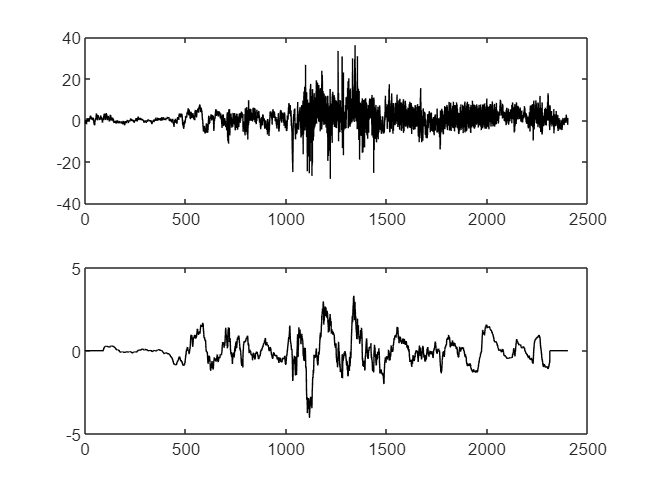

Ex=(data2.EX)';      % Ex here is actually E1 data in the field-aligned coordinates
By=(data2.BY)';      % By here is actually B2 data in the field-aligned coordinates

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Fse=32;              % MMS E field sampling rate, for THEMIS, using particle burst data, the sampling rate will be 512 
Fsb=16;              % MMS B field sampling rate, for THEMIS, there may be 16 Hz FGL data
rtimeE=0:1./Fse:length(Eperp)/Fse-1./Fse;     % construct time stamps for E  
rtimeB=0:1./Fsb:length(Bperp)/Fsb-1./Fsb;     % construct time stamps for B
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(1);           % plot to test what we have
subplot(2,1,1);        
plot(rtimeE,Eperp,'k');
subplot(2,1,2);
plot(rtimeB,Bperp,'k');

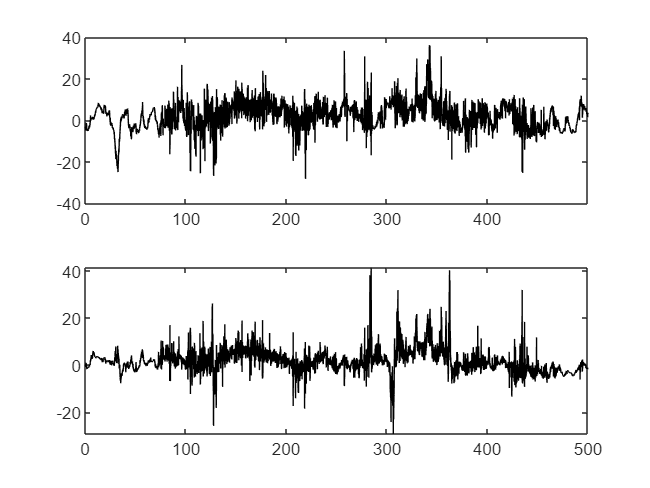

%%
indb=find(rtimeB>=1000&rtimeB<1500);    %%% select a chunk of data series, with most evident KAWs, to work with
inde=find(rtimeE>=1000&rtimeE<1500);    %%%from 06:36:40 to 06:45:00 UT
Edata=Eperp(inde);     % this is E2
Bdata=Bperp(indb);     % this is B1
Etime=rtimeE(inde)-rtimeE(inde(1));
E1=Ex(inde);
B2=By(indb);
figure(2);           % plot to show what we have
subplot(2,1,1);
plot(Etime,Edata,'k');
xlim([0 max(Etime)]);
subplot(2,1,2);
plot(Etime,E1,'k');

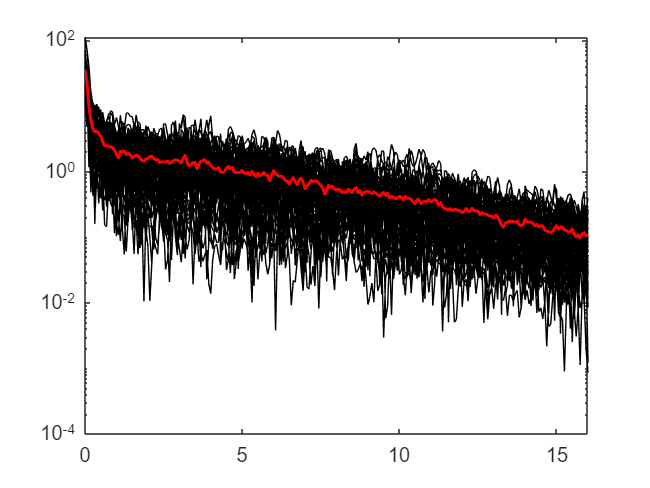

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FFT for E2 field
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
NFFT = 32*16; % 16 s window
wlen=NFFT;    % hanning window length
hp=NFFT*0.5;  % 8 s overlapping
K = sum(hann(wlen))/wlen;  % hanning weighting power
[stftV,fV,tV]=stfto(Edata,wlen,hp,NFFT,Fse);   % please refer to stfto.m file for details of FFT procedure
sV=stftV/wlen/K;           % correct for amplitudes
sV(1:end, :) = sV(1:end, :).*2;
asV=sqrt(abs(sV).^2./(Fse/NFFT));       % E2 field amplitude spectrum
indV=find(asV(1,:)>10.);       % selecting above-noise spectra
dim=length(indV);
meanE=mean(asV(:,indV),2,'omitnan');   % mean E2 spectrum
stdE=std(asV(:,indV),0,2,'omitnan');
figure(3);       % plotting to check selected E2 spectrum
for i=1:dim
    semilogy(fV,asV(:,indV(i)),'k','LineWidth',0.5);
    hold on
end
plot(fV,meanE,'r','LineWidth',1.5);
xlim([0 16]);
hold off

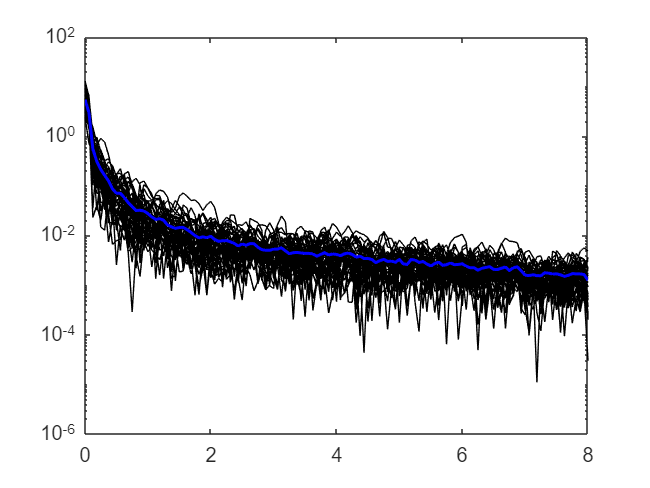

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FFT for B1 field
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[stftB,fB,tB]=stfto(Bdata,wlen/2,hp/2,NFFT/2,Fsb);       % similar FFT for B1 with half size window compare with E2
sB=stftB/wlen/K;
sB(1:end, :) = sB(1:end, :).*2;
asB=sqrt(abs(sB).^2./(Fsb/(NFFT/2.)));
psdb=log10(abs(sB).^2./(Fsb/(NFFT/2.)));
indB=find(asB(1,:)>2.0);            % select above-noise B1 spectrum
dimB=length(indB);
meanB=mean(asB(:,indB),2,'omitnan');    % mean B1 spectrum
stdB=std(asB(:,indB),0,2,'omitnan');
figure(4);
for i=1:dimB
    semilogy(fB,asB(:,indB(i)),'k','LineWidth',0.5);
    hold on
end
plot(fB,meanB,'b','LineWidth',1.5);
xlim([0 8]);
hold off


c = pcolor(tB, fB, psdb)

c =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [8 16 24 32 40 48 56 64 72 80 88 96 104 112 120 128 136 144 152 160 168 176 184 192 200 208 216 224 232 240 248 256 264 272 280 288 296 304 312 320 328 336 344 352 360 368 376 384 392 400 408 416 424 432 440 448 456 464 472 480 488]
           YData: [0 0.0625 0.1250 0.1875 0.2500 0.3125 0.3750 0.4375 0.5000 0.5625 0.6250 0.6875 0.7500 0.8125 0.8750 0.9375 1 1.0625 1.1250 1.1875 1.2500 1.3125 1.3750 1.4375 1.5000 1.5625 1.6250 1.6875 1.7500 1.8125 1.8750 1.9375 2 2.0625 2.1250 … ]
           ZData: [129×61 double]
           CData: [129×61 double]

  Show a

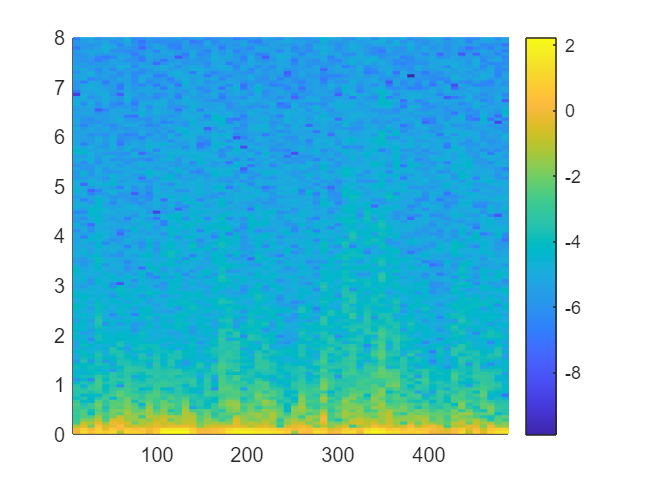

colorbar
set(c, 'EdgeColor', 'none');

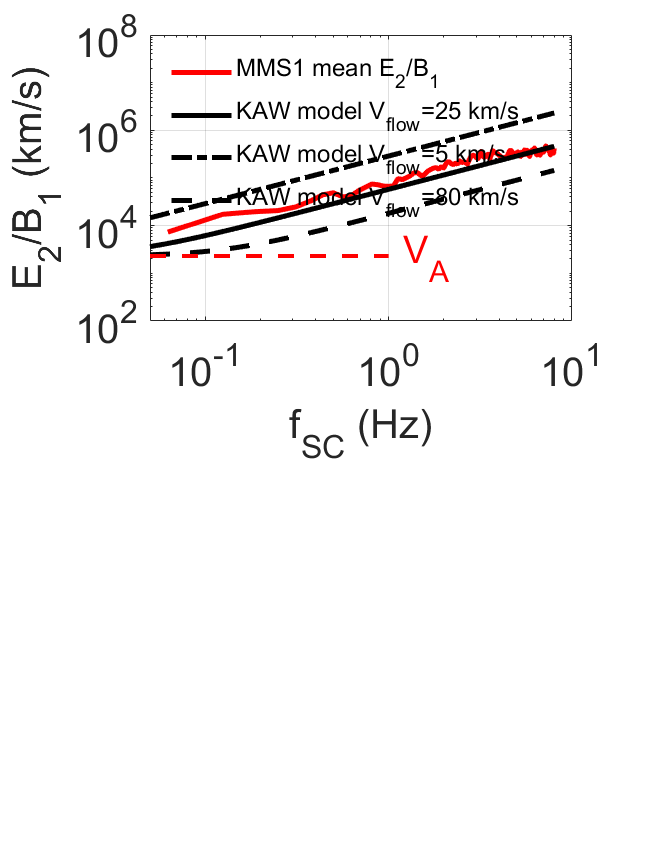

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% interpolate E2 spectrum on to B1 spectrum
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mE_int = interp1(fV, meanE, fB)';      % mean E2 spectrum
E_int(length(fB),size(asV,2))=NaN;
for i=1:dim
    E_int(:,indV(i)) = interp1(fV, asV(:,indV(i)), fB)';
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This part we apply KAW model with different ion flows based on MMS observations
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Vi=25*1000.;      % mean observed Vi in m/s during the interval
Vi2=5*1000.;      % smallest observed Vi in m/s
Vi3=80*1000.;     % most strong observed Vi in m/s  
B=75.;            % total background magnetic intensity in nT
n=0.5*1.0e6;      % total/ion density in per m^3
Ti=4000.0;        % ion temperature in keV
Te=4000.0;        % electron temperature in keV
wce=1.6*10^(-19)*B*10^(-9)/(9.1*10^(-31));      % local electron cyclotron frequency in rad/s
mi=1.673*1e-27;   % ion mass
wci=1.6*10^(-19)*B*10^(-9)/mi;      % local ion cyclotron frequency in rad/s
wpe=sqrt(n*1.6^2*10^(-38)/(8.85*10^(-12)*9.1*10^(-31)));    % local plasma frequency
mu=1.26*10^(-6);      % magnetic permeability
Va=B*1e-9/sqrt(mu*n*mi);    % Alfven speed in m/s
pi=3.1415926;    
epsilon=8.85*10^(-12);    %  diaeletric constant
ri=sqrt(2*Ti*1.6e-19/mi)/wci;   % ion thermal gyroradius in m
rs=sqrt(Te*1.6e-19/mi)/wci;     % ion acoustic ion gyroradius
kperp=2*pi.*[0.05:0.01:8.0]./Vi;    % assuming model frequency range of 0.05--8.0 Hz for KAWs, inferring k_perp based on mean ion flow velocity Vi
mod_eoverb=Va*(1+kperp.^2.*ri^2)./sqrt(1+kperp.^2.*(rs^2+ri^2));   % calculate model E/B in m/s
kperp2=2*pi.*[0.05:0.01:8.0]./Vi2;  % assuming model frequency range of 0.05--8.0 Hz for KAWs, inferring k_perp based on lower ion flow velocity Vi2
mod_eoverb2=Va*(1+kperp2.^2.*ri^2)./sqrt(1+kperp2.^2.*(rs^2+ri^2));   % calculate model E/B in m/s
kperp3=2*pi.*[0.05:0.01:8.0]./Vi3;  % assuming model frequency range of 0.05--8.0 Hz for KAWs, inferring k_perp based on larger ion flow velocity Vi3
mod_eoverb3=Va*(1+kperp3.^2.*ri^2)./sqrt(1+kperp3.^2.*(rs^2+ri^2));   % calculate model E/B in m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    
fontsize=20;        % specify configuration of plots
yn=2;
xn=1;
ydown=0.15;
ystep=0.15;
ysize=0.33;
xleft=0.23;
xstep=0.1;
xsize=0.65;
%%%%%%mysubplot(1,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
hf=figure('Name','20190929 KAW');
set(gcf,'unit','centimeters','position',[1 1 15 20]);
H1=mysubplot(1,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);    % refer to mysubplot.m file for plotting
% this part is plotting individual data points (data steps change with different time window size used in FFT), I later found it confuses people, so I comment out this part
% % for i=1:length(fB)
% %     for j=1:dimB
% %         plot(fB(i),E_int(i,indB(j))/asB(i,indB(j))*1000,'.','MarkerSize',1.5,'MarkerFaceColor','k','MarkerEdgeColor','k','linewidth',1);
% %         set(gca,'Yscale','log');
% %         set(gca,'Xscale','log');
% %         hold on
% %     end
% % end
h1=loglog(fB,mE_int./meanB.*1000,'r','LineWidth',2.5);
hold on
grid off
hold on
h2=loglog([0.05:0.01:8.0],mod_eoverb./1000,'k','Linewidth',2.5);
hold on
h3=loglog([0.05:0.01:8.0],mod_eoverb2./1000,'k-.','Linewidth',2.5);
hold on
h4=loglog([0.05:0.01:8.0],mod_eoverb3./1000,'k--','Linewidth',2.5);
hold on
h5=loglog([0.05:0.01:1.0],repmat(Va,length([0.05:0.01:1.0]),1)./1000,'r--','Linewidth',2.0);
    hold on
    text(1.2,Va/1000.0,'V_{A}','Fontsize',fontsize-1,'color','r');
set(gca,'FontSize',fontsize);
ylabel('E_{2}/B_{1} (km/s)','Fontsize',fontsize);
xlabel('f_{SC} (Hz)','Fontsize',fontsize);
xlim([0.05 10.0]);
ylim([10^2 10^8]);
set(gca,'xtick',[10^-1 10^0 10^1]);
set(gca,'ytick',[10^2 10^4 10^6 10^8]);
h=legend([h1 h2 h3 h4],{'MMS1 mean E_{2}/B_{1}','KAW model V_{flow}=25 km/s','KAW model V_{flow}=5 km/s','KAW model V_{flow}=80 km/s'},'Fontsize',fontsize-8,'Location','northwest');
set(h,'box','off');
grid on

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%Fit power law decay of KAW power to obtain input for test particle simulations
fitind=18:209;       % 1-13 Hz for kinetic branch
x=fV(fitind)';      % starting with 1 Hz
y=meanE(fitind);
z=stdE(fitind);
myfittype=fittype('a*x^(-b)','dependent',{'y'},'independent',{'x'},'coefficients',{'a','b'});

'fittype' requires Curve Fitting Toolbox.

options=fitoptions(myfittype);
options.StartPoint=[5.0,1.0];
myfit=fit(x,y,myfittype,options);
mx=double(linspace(0.1,16,1000));
my=myfit.a.*mx.^(-myfit.b);
H22=mysubplot(2,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
plot(fV(1:end)',meanE,'^','MarkerSize',6,'MarkerFaceColor',[0 1 0],'MarkerEdgecolor',[0 1 0]);
set(gca,'Yscale','log');
set(gca,'Xscale','log');
xlim([1 32]);
hold on
d=plot(fV(1:end)',meanE,'g','LineWidth',3.5);
hold on
model=plot(mx,my,'r','LineWidth',3.5);
xlabel('f_{SC} (Hz)','fontsize',fontsize);
ylabel('KAW E2 (mV/m/Hz^{0.5})','fontsize',fontsize);
xlim([0.1 32]);
ylim([0.01 30]);
set(gca,'ytick',[0.01 0.1 1.0 10]);
set(gca,'xtick',[0.1 1.0 10.0 32.0]);
hold on
line([1.0 1.0],[0.01 30],'Color',[0.8 0.8 0.8],'LineWidth',0.5,'LineStyle','-');
hold on
line([10.0 10.0],[0.01 30],'Color',[0.8 0.8 0.8],'LineWidth',0.5,'LineStyle','-');
hold on
line([0.1 32.0],[0.1 0.1],'Color',[0.8 0.8 0.8],'LineWidth',0.5,'LineStyle','-');
hold on
line([0.1 32.0],[1.0 1.0],'Color',[0.8 0.8 0.8],'LineWidth',0.5,'LineStyle','-');
hold on
l=legend([d model],'Mean E_{2} spectrum',[num2str(myfit.a,'%.1f') '*x^{- ' num2str(myfit.b,'%.1f') '}'],'Fontsize',fontsize-8,'Location','northeast');
set(l,'box','off');
box on
hold off
set(gca,'FontSize',fontsize);
%%
%%%%%%%%%%%%%% this part is my partial code to initialize simulation of KAWs parameters
%%%%%%%%%%%%%% just for your reference to specify KAWs spectrum in the simulation
%%%%%%%%%%%%%% you may have your own way of including KAW spectra in the simulation

%%%here we set up kperp*ri in the range specified by MMS observation and
%%%get electric field/potential based on observed spectrum
    Vi=25*1000.;
    B=75.;
    n=0.5*1.0e6;
    Ti=4000.0;
    Te=4000.0;
    wce=1.6*10^(-19)*B*10^(-9)/(9.1*10^(-31));
    mi=1.673*1e-27;
    wci=1.6*10^(-19)*B*10^(-9)/mi;
    wpe=sqrt(n*1.6^2*10^(-38)/(8.85*10^(-12)*9.1*10^(-31)));
    mu=1.26*10^(-6);
    Va=B*1e-9/sqrt(mu*n*mi);
    pi=3.1415926;
    epsilon=8.85*10^(-12);
    ri=sqrt(2*Ti*1.6e-19/mi)/wci;
    rs=sqrt(Te*1.6e-19/mi)/wci;
    freq=[0.0625:0.0625:8.0];     % this is the frequency range observed for KAWs, df is determined by FFT window size
    kperp=2*pi.*freq./Vi;        % Kperp is determined here by average flow velocity Vi
    mod_eoverb=Va*(1+kperp.^2.*ri^2)./sqrt(1+kperp.^2.*(rs^2+ri^2));   
    kr=kperp.*ri;

    dfnew=0.0625;    %    you can resize df here, but I use the same df, when df change, E amplitude should also change to conserve PSD
    freqnew=[0.0625:dfnew:4.0]; % this is the frequency range in Hz for KAWs in the simulation
    dwna=1.0;
    wna=[73.0:1.0:87.0];  % this is one example of the wave normal angle range I have taken, 
    
    Ew=sqrt(4.0^2*sum((freqnew).^(-1.4))*dfnew);    %<Ew^2>  4.0 m/V for KAW Eperp, as observed spectra
    fw=1/15.0;         % uiform distribution in wna (i.e., F_theta), 15 uniform angle ranges (per 1 deg) for WNA
    Ew0=sqrt(Ew^2*fw*dwna/(sum((freqnew).^(-1.4))*dfnew));     % select just one single WNA for one particular energy, so the E0*f^(-v) should be adjusted
    Eperp_new=Ew0*(freqnew).^(-0.7);
    kperpr_new=2*pi.*freqnew./Vi*ri;   
    Phi=(Eperp_new./kperpr_new).*ri*1e-6;       % hereforth, spatial scales are normalized by 1000 km
    
    % initial particle deposition at equator
   
    npart=100;
   
    y0=0.15;  % 150 km towards the front; otherwise use negative behind the front
    yp=linspace(-0.3,0.3,npart);
    xp=repmat(y0,1,npart);

    z=-3.0:0.01:3.0;
    xx=repmat(y0,1,length(z));
    ascale0=0.03;
    sina0=(sin(1.5*pi/180.0))^2;  % initial pitch angle
    Bcs=20.0;       % 20 nT for current sheet magnitude B0
    Lcs=3.0;     % 3000 km for the current sheet thickness in the z direction (normal direction)
    Bdf=20;       % 25 nT for dipolarization fronts
    Ldf=0.5;      % 500 km for dipolarization front scale in the x direction
    Lps=6.371*5.0;     % set the scale of plasma sheet to 5 Re
    ascale=0.03;
    sina2=(sin(1.5*pi/180.0))^2;
%     pos=[zeros(1,npart);yp;zeros(1,npart)]';
    pos=[xp;yp;zeros(1,npart)]';
    rng(3);
    pos_phase(1:npart,1:length(freqnew))=NaN;
    for i=1:npart
        pos_phase(i,1)=i/npart.*2*pi;
        rng('shuffle');
        pos_phase(i,2:length(freqnew))=rand(1,length(freqnew)-1).*2*pi;
    end
    
    %specify density and temperature behind the front at the equator, simplifed model are used for magnetic field

    pos_n0=0.05*(2*Bdf)./abs(Bdf.*(1+ascale-tanh(xx(1)/Ldf)))*1e6;
    pos_Ti0=4.0./(2*Bdf).^2.*(Bdf.*(1+ascale-tanh(xx(1)/Ldf))).^2;
    Bx0=Bcs.*tanh(0./Lcs)+(ascale*Bdf/sina2-Bcs)*tanh(0./Lps);
    Bz0=Bdf.*(1+ascale-tanh(xx(1)/Ldf));
    Btot0=sqrt(Bx0.^2+Bz0.^2);
    % %%
    mi=1.673*1e-27;
    pos_wci0=1.6*10^(-19).*Btot0.*10^(-9)./mi;
    pos_ri0=sqrt(2*pos_Ti0.*1000.0.*1.6e-19/mi)./pos_wci0.*1e-6;      %this part only apply for my model of density, temperature and magnetic field distribution, (if change values, need to vary this value by "coeff1* abs(Bz)/B0", where coeff1=sqrt(mi*Ti/3.2)/Bdf/1e-14, and I use Ti=4 keV)
    mu=1.26*10^(-6);
    % Alfven speed in the simulation, units normalized to 1000 km/s
    pos_Va0=Btot0.*1e-9./sqrt(mu.*pos_n0.*mi)*1e-6;    %this part only apply for my model of density, temperature and magnetic field distribution (if change values, need to vary this value by "coeff2* sqrt(abs(Bz))*B0", coeff2=1e-18/sqrt(mu*n*2*Bdf*mi), density used here is n=0.05 cc)
    
    pos_kperp=kperpr_new./pos_ri0;   % vary k_perp based on new position

    % angles is the parameter of optimum resonant wave normal angle for the electron energy and pitch angle you speicify
    %%% angles=atan(E_to_v(energy)*cos(pitch_d*pi/180)./driftavg)*180.0/pi;  
    %determined by electron energy, pitch angle, and average guiding-center drift
    angles=80.0;

    % here is one-deg WNA range used corresponding to weighted wave amplitude Ew0 in the simulation
    angle=linspace(max([angles-0.5 74.5]),min([angles+0.5 89.5]),length(freqnew)); % select ~ 1 deg WNA range 
    pos_ratio=tan(angle*pi/180.0); %this is just to relate kperp to kpara based on WNA


    %this is the conserved KAW dispersion along particle trajectory in the simulation
    pos_conserved0=pos_kperp.^2.*pos_Va0.*pos_ri0;         %x position change will change constants in C++ code



function [stft, f, t] = stfto(x, wlen, h, nfft, fs)

% function: [stft, f, t] = stft(x, wlen, h, nfft, fs)
% x - signal in the time domain
% wlen - length of the hamming window
% h - hop size
% nfft - number of FFT points
% fs - sampling frequency, Hz
% f - frequency vector, Hz
% t - time vector, s
% stft - STFT matrix (only unique points, time across columns, freq across rows)

% represent x as column-vector if it is not
if size(x, 2) > 1
    x = x';
end

% length of the signal
xlen = length(x);

% form a periodic hamming window
win = hanning(wlen);

% form the stft matrix
rown = ceil((1+nfft)/2);            % calculate the total number of rows
coln = 1+fix((xlen-wlen)/h);        % calculate the total number of columns
stft = zeros(rown, coln);           % form the stft matrix

% initialize the indexes
indx = 0;
col = 1;

% perform STFT
while indx + wlen <= xlen
    % windowing
    xw = x(indx+1:indx+wlen).*win;
    
    % FFT
    X = fft(xw, nfft);
    
    % update the stft matrix
    stft(:, col) = X(1:rown);
    
    % update the indexes
    indx = indx + h;
    col = col + 1;
end

% calculate the time and frequency vectors
t = (wlen/2:h:wlen/2+(coln-1)*h)/fs;
f = (0:rown-1)*fs/nfft;
%  f(f >= fs/2) = f(f >= fs/2) - fs;
end

function outargs=restore_idl(varargin)
% RESTORE_IDL:  restores variable from an IDL save file into Matlab
% variables.
%
% Input arguments (can appear in any order, and all are optional):
%
%   - filename: complete path specification for the save file
%   - 'lowercase': convert variable names from ALL CAPS to all lowercase
%   - 'verbose': print out analysis of file structure
%   - 'restore_verbose': print out lots of stuff while restoring variables
%   - 'debug': both verbose and restore_verbose
%
% This version restores every variable it knows how to do, and puts them
% all into the output argument array or a struct whose field names are the
% IDL variable names, and field values are the IDL variables themselves.
% The latter (single structure) method is the default.
% 
% To create a MATLAB variable from one of the fields in the single 
% structure, do this:
%   fields=fieldnames(outargs);
%   eval([fields{n} '=outargs.' fields{n} ';']);
%
%
% Output is a struct array with fields "name" and "value", where
% "name" is the name of the variable, and "value" is a cell array
% containing the variable, whatever it may be.  Could be a scalar, numeric
% array, string, struct, array of structs, nested structs, what have you.

%
% Variables appear in the save file with names in all uppercase, which is
% usually not the convention in matlab, and also regardless of whether the
% user used lower or mixed case in the IDL session that created them.  So
% there is an option here to convert names to all lowercase.  
% 
%
% Original version:
% C. Pelizzari, Oct 2013
%
% (c) 2013, 2015: University of Chicago Image Computing, Analysis and Repository
% Core Facility
%
%
% Sept 2015 - update will corrections made to restore_idl_gui in response
% to user feedback, repackage as callable function vs GUI application.

global frestore_verbose
frestore_verbose=0;
verbose=0;
dolower=0;
split=0;
% variables is a struct array that contains info about each variable found
variables=[];

filename=[];
if nargin > 0,
    for i=1:nargin
        if ischar(varargin{i}),
            mystring=varargin{i};
            fp=fopen(mystring);
            if fp > 0,
                filename=mystring;
                fclose(fp);
            else
                if strcmp(lower(mystring),'verbose'),
                    verbose=1;
                end
                if strcmp(lower(mystring),'restore_verbose'),
                    frestore_verbose=1;
                end
                if strcmp(lower(mystring),'lowercase'),
                    dolower=1;
                end
                if strcmp(lower(mystring),'debug'),
                    frestore_verbose=1;
                    verbose=1;
                end
                if strcmp(lower(mystring),'split'),
                    split=1;
                end
            end
        end
    end
end
if isempty(filename),
    [fname,pathname]=uigetfile('*.*','Select IDL save file to restore');
    filename=fullfile(pathname,fname);
end
disp(filename);
fid=fopen(filename);
signature=char(fread(fid,2,'char')');
if verbose, disp(['SIGNATURE = ' signature]), end
alldone=0;
 % convert all variable names to lowercase
if ~strcmp(signature,'SR'),
    disp(['unrecognized signature - terminating.']);
    alldone=1;
end

if ~alldone,
    
recfmts={'COMMON_VARIABLE' 'VARIABLE' 'SYSTEM_VARIABLE' '' '' 'END_MARKER' ...
'' '' '' 'TIMESTAMP' '' 'COMPILED' 'IDENTIFICATION' 'VERSION' ...
'HEAP_HEADER' 'HEAP_DATA' 'PROMOTE64' '' 'NOTICE'};

if verbose, 
    disp('----- Analysis of file structure: -----');
    %fseek(fid,4,'bof');
    nextptr=4;
    while(1)
        fseek(fid,nextptr,'bof');
        recfmt=fread(fid,1,'uint32',0,'b');
        fprintf(1,'Offset %d: record type %s\n', nextptr,recfmts{recfmt});
        if recfmt==6, break, end
        nextptr=fread(fid,1,'uint32',0,'b');
    end
    disp('----------');
end
varnames={};
nextptr=4;
while (1)
 fseek(fid,nextptr,'bof');
    thisptr=nextptr;
    rhdr=fread(fid,1,'uint32',0,'b');
    if feof(fid), break; end % bail out if hit EOF
    nextptr=fread(fid,1,'uint32',0,'b');
    nextptr1=fread(fid,1,'uint32',0,'b');
    unknown=fread(fid,1,'uint32');
    
    % specific format of each type of record is documented in C. Markwardt's
    % description of the file format   
    switch rhdr
        case 10    %timestamp
            if (nextptr < 1024),
                disp('version offset < 1024... probably a compressed file');
                disp('sorry, can''t deal with this.  if possible, save without the "/COMPRESS" flag.')
                return
            end
            unknown=fread(fid,256,'uint32');
            strlen=fread(fid,1,'uint32',0,'b');
            datestring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            strlen=fread(fid,1,'uint32',0,'b');
            userstring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            strlen=fread(fid,1,'uint32',0,'b');
            hoststring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            if verbose,
            disp(['TIMESTAMP:  date, user, host =  ' datestring '  ' userstring '  ' hoststring])
            end
        case 14    % version       
            fmt=fread(fid,1,'uint32',0,'b');
            strlen=fread(fid,1,'uint32',0,'b');
            archstring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            strlen=fread(fid,1,'uint32',0,'b');
            osstring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            strlen=fread(fid,1,'uint32',0,'b');
            releasestring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            if verbose,
            disp(['VERSION: arch, os, release = ' archstring osstring releasestring])
            end
        case 19
            if verbose, disp('NOTICE:'); end
            strlen=fread(fid,1,'uint32',0,'b');
            notestring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
        case 2  % this is the most important one - actual data
            varstring='';
            % here's the name - length first, then the string
            strlen=fread(fid,1,'uint32',0,'b');
            varname=deblank(char(fread(fid,4*ceil(strlen/4),'char')'));
            variables(end+1).name=varname;
            variables(end).ptr=thisptr;
            % typecode tells type of each element in variable
            typecode=fread(fid,1,'uint32',0,'b');
            % varflags tells if it's an array or scalar
            varflags=fread(fid,1,'uint32',0,'b');
            switch typecode
                case 1
                    mytype='uint8';
                case 2
                    mytype='int16';
                case 3
                    mytype='int32';
                case 4
                    mytype='single';
                case 5
                    mytype='double';
                case 6
                    mytype='complex';
                case 7
                    mytype='string';
                case 8
                    mytype='structure';
                case 9
                    mytype='double complex';
                case 11
                    mytype='object pointer';
                case 12
                    mytype='uint16';
                case 13
                    mytype='uint32';
                case 14
                    mytype='int64';
                case 15
                    mytype='uint64';
            end
            % varstring is our description for the selection listbox
            varstring=[ varname ':  '  mytype];
                   
            if ~bitand(varflags,4),  % scalar
                %disp('    SCALAR ');
                varstring=[varstring ' SCALAR'];
            elseif bitand(varflags, 4)  % array               
                arrstart=fread(fid,1,'uint32',0,'b');
                nbytes_el=fread(fid,1,'uint32',0,'b');
                nbytes=fread(fid,1,'uint32',0,'b');
                nelements=fread(fid,1,'uint32',0,'b');
                ndims=fread(fid,1,'uint32',0,'b');
                stuff=fread(fid,2,'uint32',0,'b');
                nmax=fread(fid,1,'uint32',0,'b');
                dims=fread(fid,nmax,'uint32',0,'b')';
                varstring=[varstring '  ARRAY: ' num2str(dims(1:max([2 ndims])))];

            end
            if verbose, disp(varstring), end
            varnames{end+1}=varstring;
        case 6
            if verbose, disp('END'); end
            break

        otherwise
            break;
    end
end


%fclose(fid);
end    %if not alldone
choices=1:numel(variables);
if split,
    outargs=struct('name','','value',{});
else
    outargs=struct;
end
for whichone=choices,
    % point to proper place in file
    nextptr=variables(whichone).ptr;
    % go there
    fseek(fid,nextptr,'bof');
    thisptr=nextptr;
    % read the record header
    rhdr=fread(fid,1,'uint32',0,'b');
    %if feof(fid), break; end
    nextptr=fread(fid,1,'uint32',0,'b');
    nextptr1=fread(fid,1,'uint32',0,'b');
    unknown=fread(fid,1,'uint32');
    switch rhdr
       case 2 % variable record - read in some data and create a variable
            varstring='';
            strlen=fread(fid,1,'uint32',0,'b');
            varname=deblank(char(fread(fid,4*ceil(strlen/4),'char')'));
            
            % convert to lowercase for Matlab variable naming if desired
            if dolower, varname=lower(varname); end
            
            typecode=fread(fid,1,'uint32',0,'b');
            varflags=fread(fid,1,'uint32',0,'b');
            switch typecode
                case 1
                    mytype='uint8';
                case 2
                    mytype='int16';
                case 3
                    mytype='int32';
                case 4
                    mytype='single';
                case 5
                    mytype='double';
                case 6
                    mytype='complex';
                case 7
                    mytype='string';
                case 8
                    mytype='structure';
                case 9
                    mytype='double complex';
                case 11
                    mytype='object pointer';
                case 12
                    mytype='uint16';
                case 13
                    mytype='uint32';
                case 14
                    mytype='int64';
                case 15
                    mytype='uint64';
            end
            varstring=[ varname ':  '  mytype];
            if frestore_verbose,disp(varstring),end
            thevar = [];
            if ~bitand(varflags,4),  % scalar
                varstring=[varstring ' SCALAR'];
                thevar=read_idl_scalar(fid,typecode);
                
                if ~isempty(thevar),
                    disp(['creating ' varstring]);
                    if split,
                        narg=numel(outargs)+1;
                        outargs(narg).name=varname;
                        outargs(narg).value=thevar;
                    else
                        outargs.(varname)=thevar;
                    end
               %     thecommand= ['global thevar; ' varname ' = thevar;'];
               %     evalin('base',thecommand);
                end
            elseif bitand(varflags, 4)  % array (also includes structures)
                if frestore_verbose,disp('doing an array'),end
                thevar=[];
                arrdesc = parse_array_descriptor(fid);
                dims=arrdesc.dims;
                ndims=arrdesc.ndims;

                varstring=[varstring '  ARRAY: ' num2str(dims(1:max([2 ndims])))];
                thevar=read_idl_array(fid,arrdesc,typecode,dolower);
                if ~isempty(thevar),
                    disp(['creating ' varstring]);
                    thevar= reshape(thevar,dims(1:max([2 ndims])));
                    if split,
                        narg=numel(outargs)+1;
                        outargs(narg).name=varname;
                        outargs(narg).value=thevar;  
                    else
                        outargs.(varname)=thevar;
                    end
%                     thecommand=['global thevar; ' varname ' = squeeze(thevar);'];
%                     evalin('base', thecommand);

                end

            end
            if frestore_verbose,
                if numel(thevar) <= 20, thevar, end, 
            end
        otherwise
            % not a variable record, nothing for us to do
    end
end
fclose(fid);
if frestore_verbose && ~isempty(varnames), disp('created new variables '), disp(varnames'),end
end


function mytype = idl_element_type( typecode)
%IDL_ELEMENT_TYPE
%   returns the string descriptor ('float32','int16', etc) given an IDL
%   typecode (a number from 1-15)

    switch typecode
        case 1
            mytype='uint8';
        case 2
            mytype='int16';
        case 3
            mytype='int32';
        case 4
            mytype='single';
        case 5
            mytype='double';
        case 6
            mytype='complex';
        case 7
            mytype='string';
        case 8
            mytype='structure';
        case 9
            mytype='double complex';
        case 11
            mytype='object pointer';
        case 12
            mytype='uint16';
        case 13
            mytype='uint32';
        case 14
            mytype='int64';
        case 15
            mytype='uint64';
    end
end

function strucdesc=new_structure_descriptor()
%NEW_STRUCTURE_DESCRIPTOR - creates a blank structure descriptor record
strucdesc=struct('structstart',0,'name','','predef',0,'ntags',0,...
    'nbytes',0,'tagtable',struct(),'tagnames','','arrtable',[],...
    'structtable',[],'classname','','nsupclasses',0,...
    'supclassnames',0,'supclasstable',[]);
end
function arrdesc = parse_array_descriptor(fid)
    arrdesc=[];
    arrdesc.arrstart=fread(fid,1,'uint32',0,'b');
    arrdesc.nbytes_el=fread(fid,1,'uint32',0,'b');
    arrdesc.nbytes=fread(fid,1,'uint32',0,'b');
    arrdesc.nelements=fread(fid,1,'uint32',0,'b');
    arrdesc.ndims=fread(fid,1,'uint32',0,'b');
    stuff=fread(fid,2,'uint32',0,'b');
    arrdesc.nmax=fread(fid,1,'uint32',0,'b');
    arrdesc.dims=fread(fid,arrdesc.nmax,'uint32',0,'b')';
end
function strucdesc = read_structure_descriptor(fid,varargin)
% READ_STRUCTURE_DESCRIPTOR - get structure descriptor record from IDL save
% file stream
%
% C. Pelizzari, October 2013
%

strucdesc=new_structure_descriptor; % initialize structure fields

% read start code?  default no
if nargin > 1 && varargin{1},
    strucdesc.structstart=fread(fid,1,'uint32',0,'b');
end
verbose=0;
% first thing is the structure name (not the variable name, but the
% structure type definition name.  we already know the variable name)
strlen=fread(fid,1,'uint32',0,'b');
strucdesc.name=deblank(char(fread(fid,4*ceil(strlen/4),'char')'));
strucdesc.predef=fread(fid,1,'uint32',0,'b'); % predef - we don't handle it
strucdesc.ntags=fread(fid,1,'uint32',0,'b'); % ntags - # of fields in struct
nbytes=fread(fid,1,'uint32',0,'b'); % this is not used but have to read it
% tagtable has a descriptive entry for each tag (field)
strucdesc.tagtable=struct('offset',[],'typecode',[],'tagflags',[],'name',[]);
for n = 1:strucdesc.ntags
    myoff=fread(fid,1,'uint32',0,'b'); % offset - not used
    mycode=fread(fid,1,'uint32',0,'b'); % type code - what kind of data
    myflags=fread(fid,1,'uint32',0,'b'); % flags - array, structure, etc
    strucdesc.tagtable(n).offset=myoff;
    strucdesc.tagtable(n).typecode=mycode;
    strucdesc.tagtable(n).tagflags=myflags;
end
% next we get all the field names.  put them into the tabtable for
% convenience.  Note we always read a multiple of 4 bytes since the whole
% file structure is organized on 4-byte boundaries.
for n=1:strucdesc.ntags
    strlen=fread(fid,1,'uint32',0,'b');
    strucdesc.tagtable(n).name=...
        deblank(char(fread(fid,4*ceil(strlen/4),'char')'));
end
% see how many arrays and structures there are - will have to process them
myflags=vertcat(strucdesc.tagtable(:).tagflags);
arrflag=hex2dec('04'); % flag for an array
arrmask=bitand(myflags,repmat(arrflag,strucdesc.ntags,1)) > 0;
structflag=hex2dec('20'); % flag for a structure
structmask=bitand(myflags,repmat(structflag,strucdesc.ntags,1)) > 0;
numarrays=numel(find(arrmask));
numstructs=numel(find(structmask));

% read in descriptors for the arrays.  Note that if there are structure
% fields, each of them will also have an array descriptor since structures
% are always contained in arrays, even if they are 1x1.
for n=1:numarrays
       arrdesc =  parse_array_descriptor(fid);
       if n==1, 
           strucdesc.arrtable=arrdesc; 
       else
           strucdesc.arrtable(n)=arrdesc;
       end
end
% read in descriptors for the structures
for n=1:numstructs
       sdesc =  read_structure_descriptor(fid,1);
       if n==1, 
           strucdesc.structtable=sdesc; 
       else
           strucdesc.structtable(n)=sdesc;
       end
end
% if verbose
%     strucdesc
%     for n=1:numarrays
%         strucdesc.arrtable(n)
%     end
% end
end
function thevar = read_idl_structure_new( fid, strucdesc,varargin )
%READ_IDL_STRUCTURE_NEW - read IDL structure data from open file, based on
% information in structure descriptor.
%
% C. Pelizzari Oct 2013

global frestore_verbose

% structure data is preceded by the startcode, a 32-bit integer "7".
if nargin>2 && varargin{1}, 
    startcode=fread(fid,1,'uint32',0,'b');
end
% do we need to convert all tagnames to lower case? default no
dolower=0;
if nargin > 3, dolower=varargin{2}; end
if nargin > 4, nelements=varargin{3};end
if frestore_verbose, 
    disp(['read_idl_structure_new: nelements= ' num2str(nelements) ' at ' num2str(ftell(fid))]);
end
% our output structure

thevar=cell(nelements,1);
%thevar=struct;
ntags=numel(strucdesc.tagtable);  % number of fields (tags)
myflags=vertcat(strucdesc.tagtable(:).tagflags); % flags - array, structure

% find out if there are any tags which are arrays or structures
arrflag=hex2dec('04');  % this marks an array
structflag=hex2dec('20'); % this marks a structure, which will probably 
                            % also be marked as an array
arrmask=bitand(myflags,repmat(arrflag,strucdesc.ntags,1)) > 0;
numarrays=numel(find(arrmask));
structmask=bitand(myflags,repmat(structflag,strucdesc.ntags,1)) > 0;
numstructs=numel(find(structmask));
readstart=0;
for nel=1:nelements
    if frestore_verbose && nelements > 1, disp(['reading structure ' num2str(nel) ' of ' num2str(nelements)]);end
    narr=0; % which of the arrays in our table are we processing
    nst=0;
    thevar{nel}=struct;
    for n=1:ntags
        if structmask(n),
            nst=nst+1;
            % skip the array table entry corresponding to this -
            % structures also get flagged as arrays, which we will ignore
            if arrmask(n),
                narr=narr+1;
            end
            % nested structures don't have a startcode, just read the data
            if frestore_verbose,
                disp(['tag number ' num2str(n) ':going to read structure, nelements= ' num2str(strucdesc.arrtable(narr).nelements) ...
                ' at offset ' num2str(ftell(fid))]);
            end
            thisfield=read_idl_structure_new(fid,strucdesc.structtable(nst),0,dolower,strucdesc.arrtable(narr).nelements);
            %thisfield=read_idl_array(fid,strucdesc.arrtable(narr),...
                %strucdesc.tagtable(n).typecode,dolower,readstart,strucdesc);
        elseif arrmask(n),
            narr=narr+1;
            if frestore_verbose, 
            disp(['tag number ' num2str(n) ':going to read array of ' idl_element_type(strucdesc.tagtable(n).typecode) ...
                ' at offset ' num2str(ftell(fid))])
            end
            thisfield=read_idl_array(fid,strucdesc.arrtable(narr),...
                strucdesc.tagtable(n).typecode,dolower,readstart);
        else
            if frestore_verbose,
            disp(['tag number ' num2str(n) ':going to read scalar ' idl_element_type(strucdesc.tagtable(n).typecode) ...
                ' at offset ' num2str(ftell(fid))])
            end
            thisfield=read_idl_scalar(fid,strucdesc.tagtable(n).typecode,0);

        end
        % put data into the appropriate field in our output structure
        name=strucdesc.tagtable(n).name;
        if dolower, name=lower(name);end
        thevar{nel}.(name)=thisfield;
    end
    readstart=0;
    %pause
end
if nelements==1, thevar=thevar{1}; end % no need for cell if only one struct
end


function [ thevar ] = read_idl_array( fid,arrdesc,typecode,varargin )
%READ_IDL_ARRAY - read in array from save file input stream based on array
% descriptor
%
% C. Pelizzari October 2013
global frestore_verbose
    % convert name to lowercase? default no
    if frestore_verbose,
    disp(['reading array, typecode= ' idl_element_type(typecode)])
    end
     dolower=0;
     if nargin > 3, dolower=varargin{1}; end
     readstart=1;
     if nargin > 4, readstart=varargin{2}; end
     strucdesc=[];
     if nargin > 5, strucdesc=varargin{3}; end
     
     mytype=idl_element_type(typecode); % what kind of data is it
     nelements=arrdesc.nelements; % how many of them
     ndims=arrdesc.ndims; % dimensionality of the array
     dims=arrdesc.dims; % vector of array dimensions
     if frestore_verbose, 
     disp([num2str(nelements) ' ' mytype  ' ' num2str(ndims) ' ' num2str(dims)])
     end
     if (typecode==7)
         thevar = {}; % array of strings may not all be same size - use cell
     elseif (typecode==8)
         thevar=cell(nelements,1); % easiest to use cell for structs too
                                              % since matlab is not very
                                              % smart about arrays of
                                              % structs, e.g. only 1D
     else thevar=[]; 
     end % our output array
     if readstart,startcode=fread(fid,1,'uint32',0,'b'); end % skip the startcode
     switch typecode
        case 1
            lenagain=fread(fid,1,'uint32',0,'b');
            thevar=cast(fread(fid,lenagain,'uint8',0,'b'),mytype);
            leftover=4*ceil(lenagain/4)-lenagain;
            if leftover, fseek(fid,leftover,0); end % move to word boundary
        case {2, 3}
            instuff=fread(fid,nelements,'int32',0,'b');
            thevar=cast(instuff,mytype);
        case 4
            thevar=cast(fread(fid,nelements,'float32',0,'b'),mytype);    
        case 5
            thevar=cast(fread(fid,nelements,'float64',0,'b'),mytype);
        case 6
            thevar=fread(fid,2*nelements,'float32',0,'b');
            thevar=reshape(thevar,nelements,2);
            thevar=complex(thevar(:,1),thevar(:,2));
        case 7  % string
            for thiselement = 1:nelements
            strlng=fread(fid,1,'uint32',0,'b');
                if ~strlng,
                    thevar{thiselement}=''; % zero length string has no further info
                else
                    strlng=fread(fid,1,'uint32',0,'b'); %length again
                    thevar{thiselement}=strtrim(char(fread(fid,4*ceil(strlng/4),'char')'));
                end
            end
        case 8  % structure - next thing in the file is the descriptor
             
             if isempty(strucdesc), strucdesc = read_structure_descriptor(fid,0); end
             if frestore_verbose,
                 disp('strucdesc.tagtable:')
                for ntag=1:numel(strucdesc.tagtable)
                     disp([strucdesc.tagtable(ntag).name ' ' ...
                     idl_element_type(strucdesc.tagtable(ntag).typecode) ' ' ...
                     num2str(strucdesc.tagtable(ntag).offset) ' '])
                end
                disp('strucdesc.arrtable:')
                for narr=1:numel(strucdesc.arrtable)
                 disp([num2str(strucdesc.arrtable(narr).arrstart) ' '...
                     num2str(strucdesc.arrtable(narr).nbytes_el) ' ' ...
                     num2str(strucdesc.arrtable(narr).nbytes) ' ' ...
                     num2str(strucdesc.arrtable(narr).nelements) ' ' ...
                     num2str(strucdesc.arrtable(narr).ndims) ' ' ...
                     num2str(strucdesc.arrtable(narr).nmax) ' ' ...
                     num2str(strucdesc.arrtable(narr).dims)])
                end
                disp('strucdesc.structable:')
                 strucdesc.structtable
                 numel(strucdesc.structtable)
                 for nstruct=1:numel(strucdesc.structtable)

                      disp(['strucdesc.structtable(' num2str(nstruct) '):'])
                     strucdescn=strucdesc.structtable(nstruct)
                      disp(['strucdesc.structtable(' num2str(nstruct) ').tagtable:'])
                    for ntag=1:numel(strucdescn.tagtable)
                                 disp([strucdescn.tagtable(ntag).name ' ' ...
                                 idl_element_type(strucdescn.tagtable(ntag).typecode) ' ' ...
                                 num2str(strucdescn.tagtable(ntag).offset) ' '])
                    end
                    disp(['strucdesc.structtable(' num2str(nstruct) ').arrtable:'])
                    for narr=1:numel(strucdescn.arrtable)
                                 disp([num2str(strucdescn.arrtable(narr).arrstart) ' '...
                                     num2str(strucdescn.arrtable(narr).nbytes_el) ' ' ...
                                     num2str(strucdescn.arrtable(narr).nbytes) ' ' ...
                                     num2str(strucdescn.arrtable(narr).nelements) ' ' ...
                                     num2str(strucdescn.arrtable(narr).ndims) ' ' ...
                                     num2str(strucdescn.arrtable(narr).nmax) ' ' ...
                                     num2str(strucdescn.arrtable(narr).dims)])
                    end
                                 
                 end
             end
             % now read what the descriptor says
             if frestore_verbose,
                 disp(['reading structure array of ' num2str(nelements)])
             end
             thevar=read_idl_structure_new(fid,strucdesc,1,dolower,nelements);
             %  if it's an array of structures, read the rest of them
             %  note that subsequent ones do not have the start code
             %for n=2:nelements
                %thevar{n}=read_idl_structure_norecurse(fid,strucdesc,0,dolower) ; 
             %end
        case 9
            thevar=fread(fid,2*nelements,'float64',0,'b');  
            thevar=reshape(thevar,nelements,2);
            thevar=complex(thevar(:,1),thevar(:,2));
        case {12, 13}
            thevar=cast(fread(fid,nelements,'uint32',0,'b'),mytype);
        case 14
            thevar=cast(fread(fid,nelements,'int64',0,'b'),mytype);
        case 15
            thevar=cast(fread(fid,nelements,'uint64',0,'b'),mytype);
         otherwise
             return
     end
    thevar=reshape(thevar,dims(1:max([2 ndims])));
    if iscell(thevar) && numel(thevar) == 1,
        thevar = thevar{1};
    end
end

function thevar = read_idl_scalar( fid,typecode,varargin )
% READ_IDL_SCALAR - reads a scalar variable from IDL save file stream
%
% C. Pelizzari, October 2013
%
    ifstart=1;  % read a start code first? default=yes
    if nargin > 2, ifstart=varargin{1};end % override default
    
    thevar=[];
    mytype=idl_element_type(typecode);  % what kind of variable?

    if ifstart, startcode=fread(fid,1,'uint32',0,'b');end

    switch typecode
        case 1  % byte data
            len=fread(fid,1,'uint32',0,'b');
            thevar=cast(fread(fid,1,'uint8',0,'b'),mytype);
            fseek(fid,3,0); % align on next word boundary
        case {2, 3}  % integers: 16 or 32 bit, saved as 32 bit
            thevar=cast(fread(fid,1,'int32',0,'b'),mytype);
        case 4  % float
            thevar=cast(fread(fid,1,'float32',0,'b'),mytype);
        case 5  % double
            thevar=cast(fread(fid,1,'float64',0,'b'),mytype);
        case 6 % single complex
            thevar=fread(fid,2,'float32',0,'b');
            thevar=complex(thevar(1),thevar(2));
        case 7  % string
             strlng=fread(fid,1,'uint32',0,'b');
             if ~strlng,
                thevar=''; % zero length (null) string has no further info
             else
                strlng=fread(fid,1,'uint32',0,'b');  %another copy of length
                thevar=strtrim(char(fread(fid,4*ceil(strlng/4),'char')'));
             end          
        case 9  % double complex
            thevar=fread(fid,2,'float64',0,'b');
            thevar=complex(thevar(1),thevar(2));
        case {12, 13}  % unsigned ints 16 and 32 bit - saved as 32
            thevar=cast(fread(fid,1,'uint32',0,'b'),mytype);
        case 14 % long int
            thevar=cast(fread(fid,1,'int64',0,'b'),mytype);
        case 15 % long unsigned int
            thevar=cast(fread(fid,1,'uint64',0,'b'),mytype);                    
        otherwise

    end
end

function H=mysubplot(num,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize)
% figure
% xn=4;
% yn=3;
% xleft=0.1;
% xstep=0;
% xsize=0.2;
% ydown=0.1;
% ystep=0;
% ysize=0.25;
% H1=mysubplot(1,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H2=mysubplot(2,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H3=mysubplot(3,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H4=mysubplot(4,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H5=mysubplot(5,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H6=mysubplot(6,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H7=mysubplot(7,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H8=mysubplot(8,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H9=mysubplot(9,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H10=mysubplot(10,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H11=mysubplot(11,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);
% H12=mysubplot(12,xn,yn,xleft,xstep,xsize,ydown,ystep,ysize);

j=yn-floor(num/xn);
i=mod(num,xn);
if i==0
    i=xn;
    j=j+1;
end
%num=xn*(yn-j)+i;
H=axes('Units','normalized','Position',[xleft+(i-1)*xsize+(i-1)*xstep ydown+(j-1)*ysize+(j-1)*ystep xsize ysize]);

% for j=1:yn
%     for i=1:xn
%         H(xn*(yn-j)+i)=axes('Units','normalized','Position',[xleft+(i-1)*xsize+(i-1)*xstep ydown+(j-1)*ysize+(j-1)*ystep xsize ysize]);
%     end
% end
end